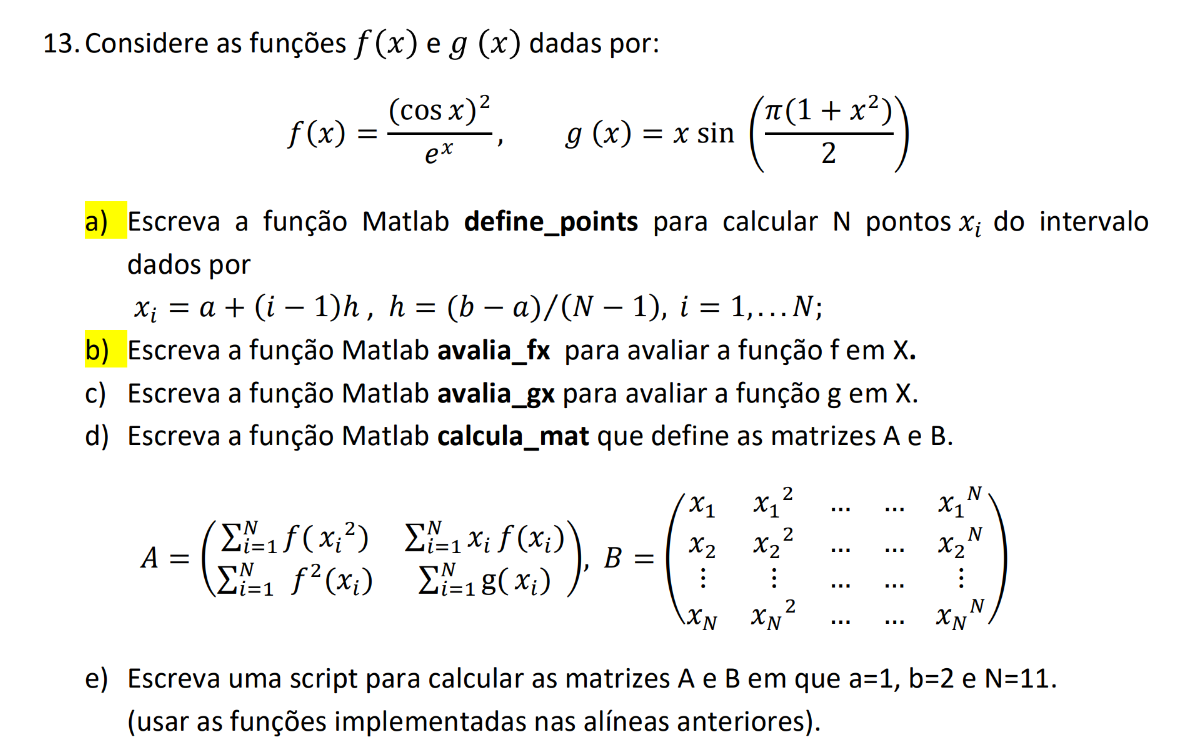

a)

function [X] = define_points(a,b,N)
    h = (b-a)/(N-1);
    X = a + (0:N-1) * h;
end
X = define_points(1,100,50);
disp(X)

    1.0000    3.0204    5.0408    7.0612    9.0816   11.1020   13.1224   15.1429   17.1633   19.1837   21.2041   23.2245   25.2449   27.2653   29.2857   31.3061   33.3265   35.3469   37.3673   39.3878   41.4082   43.4286   45.4490   47.4694   49.4898   51.5102   53.5306   55.5510   57.5714   59.5918   61.6122   63.6327   65.6531   67.6735   69.6939   71.7143   73.7347   75.7551   77.7755   79.7959   81.8163   83.8367   85.8571   87.8776   89.8980   91.9184   93.9388   95.9592   97.9796  100.0000



b)

function [Fx] = avalia_fx(X)
    Fx = cos(X).^2./exp(X);
end
Fx = avalia_fx(X);
disp(Fx)

    0.1074    0.0481    0.0007    0.0004    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000



c)

function [Gx] = avalia_gx(X)
    Gx = X .* sin((pi/2) * (1 + X.^2));
end
Gx = avalia_gx(X);
disp(Gx)

    0.0000   -0.5793   -3.0255   -6.8933   -6.6587    4.3340   12.4887   -7.0042  -10.5689   19.1795  -17.4069   12.9612  -11.6328   15.9192  -25.0435   31.0988  -17.0707  -21.0486   32.7843   22.9132  -22.4077  -43.3393  -37.1736  -24.3417  -18.2112  -23.4662  -39.3912  -55.0666  -42.6189   17.2543   61.2536  -11.3866  -57.3098   60.2230  -25.3063   -6.8862   22.2248  -19.3594   -3.6622   45.7382  -81.0232   49.4819   55.6550  -65.5539  -76.1344    1.9843   67.0949   92.7568   97.9796  100.0000



d)

function [A,B] = calcula_mat(X,f,g)

    N = length(X);

    % Matriz A
    A11 = sum(f(X.^2));
    A12 = sum(X.*f(X));
    A21 = sum(f(X).^2);
    A22 = sum(g(X));

    A = [
        A11 A12;
        A21 A22
         ];

    % Matriz B
    B = X(:).^(1:N);
end